Ejemplo de diseño de filtro digital - Función de transformación - paso bajo a paso alto

autor: Filipuzzi, Fernando Rafael

versión: 20230314

Matlab:2022b

function [B,A]=mi_lp2bp(Bs,As, w0, B)

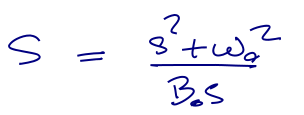

    syms s;
    H(s)=poly2sym(Bs,s)/poly2sym(As,s);

    H(s)=collect( H( (s^2+w0^2)/(B*s) ) );
    
    [num,den]=numden(H(s));
    B=sym2poly(num);
    A=sym2poly(den);

end